# Temporal Modulation Filtering and Wavelet Analysis of Recorded Speech

### 2.1 Title and Author Information

ELEC5305 Acoustics, Speech and Signal Processing | Audio Processing Report 2

Author: Yixiang Ma | Student ID: 550762913 | Date: 29 October 2026

clear; close all; clc;
reportFolder = pwd;
if ~isfile(fullfile(reportFolder,'voicebank_p232_003.wav'))
    reportFolder = fullfile(pwd,'Report2 YixiangMa');
end
assert(isfile(fullfile(reportFolder,'voicebank_p232_003.wav')), ...
    'Set Current Folder to the extracted Report2 YixiangMa folder.');
addpath(reportFolder);
assert(exist('cwt','file')==2, 'Wavelet Toolbox is required.');

### 2.2 Objective

This report investigates how restricting temporal modulations changes a recorded speech signal. A two-dimensional Fourier transform of a log-magnitude spectrogram is used to apply 4, 8, and 16 Hz temporal low-pass (LP) masks. The experiment checks reconstruction, measures waveform and envelope fidelity, and uses the continuous wavelet transform to inspect local time-frequency changes. Unlike Report 1's synthetic-signal finite impulse response (FIR) noise reduction, the aim here is to analyse speech dynamics, not to demonstrate denoising or claim improved intelligibility.

### 2.3 Background

The short-time Fourier transform (STFT) describes how acoustic frequency content evolves. Its window length controls the time-frequency trade-off, while its hop determines the sampling rate of the spectrogram's time axis. A second Fourier transform across the spectrogram reveals temporal modulation in hertz and spectral modulation in cycles per kilohertz [1,3,4]. These modulation frequencies describe changes in a spectral pattern, not the acoustic frequencies of the speech waveform.

Speech-modulation studies motivate examining low temporal rates, but acoustic similarity alone does not establish intelligibility [3]. Here, filtering is applied to the log magnitude while the original STFT phase is retained. An arbitrary modified magnitude and the retained phase need not form a consistent STFT of any waveform. Reanalysis therefore provides a useful consistency check.

The continuous wavelet transform (CWT) provides a complementary, scale-dependent view: high-frequency wavelets are shorter in time than low-frequency wavelets. MATLAB's analytic Morlet wavelet and L1 normalisation are used [2,5]. The cone of influence (COI) identifies boundary-sensitive coefficients, which are excluded from the displayed scalograms [6].

### 2.4 Methodology and Implementation

The input is the unchanged clean VoiceBank utterance p232_003.wav from the Edinburgh dataset [7], not a personal recording. MATLAB resample converts its native 48 kHz rate to 16 kHz with anti-alias filtering [8]. The mean is removed and the input peak is scaled once to 0.8. Every condition uses this same reference. A 512-sample periodic Hann window, 128-sample hop, and 512-point fast Fourier transform (FFT) correspond to 32 ms, 8 ms, and a 125 Hz frame rate.

Log magnitudes are floored 120 dB below the maximum STFT magnitude. Before modulation filtering, 63 neighbouring frames are reflected at each time boundary (about 0.5 s). The even temporal mask is unity up to 0.8 times its stop frequency, has a raised-cosine transition, and is zero at and above 4, 8, or 16 Hz. Spectral modulation is not filtered. Symmetric masks preserve real-valued log magnitudes. Inverse transforms, original-phase reuse, and squared-window overlap normalisation reconstruct equal-length outputs. The bypass uses the original complex STFT, avoiding the log floor.

A known 4/16 Hz log-spectrogram calibration tests the mask before interpreting speech. Fidelity is scored from 0.5 s to 0.5 s before the utterance ends. Reference-to-error signal-to-noise ratio (SNR), 20 ms root-mean-square (RMS) envelope correlation, log-spectrum root-mean-square error (RMSE), and STFT consistency error are reported. No output gain fitting or delay search is used. One common attenuation is applied only to listening WAV files. For CWT inspection, an 800 ms interval is selected by the largest reference RMS-envelope change outside 0.7 s margins. This is an offline demonstration on one utterance, not a listening study or a causal system.

The main operations are defined below. Here n is a sample index, k is an acoustic-frequency bin, m is a frame, L is window length, H is hop, N is FFT length, and w is the Hann window.


$$S[k,m]=\sum_{n=0}^{L-1}x[n+mH]w[n]e^{-j2\pi kn/N}$$


A is the floored log-magnitude spectrogram. M is its two-dimensional transform, with F frequency rows and T time columns. Temporal and spectral modulation axes follow the sampling intervals, not the audio FFT axis.


$$A[k,m]=20\log_{10}(\max(|S[k,m]|,\epsilon)),\qquad M=\mathrm{FFT2}(A_{\mathrm{pad}})$$



$$f_t(v)=v\frac{f_s}{HT},\qquad \nu_s(u)=u\frac{1000}{F\Delta f},\qquad \Delta f=\frac{f_s}{N}$$


With an even temporal mask B, the inverse two-dimensional FFT (IFFT2) is followed by cropping the reflected frames. The original phase is then restored. Display-only modulation maps additionally remove row means and apply a separable Hann taper; that display preprocessing is not used for filtering or inversion.


$$\widetilde{A}=\mathrm{Re}\{\mathrm{IFFT2}(B\odot M)\},\qquad \widetilde{S}=10^{\widetilde{A}/20}e^{j\arg S}$$



$$\widehat{x}[n]=\frac{\sum_m w[n-mH]\widetilde{s}_m[n-mH]}{\sum_m w^2[n-mH]}$$


The denominator is used only where positive; padding keeps every retained speech sample covered. The L1-normalised CWT uses scale a, time shift b, and the conjugate Morlet wavelet. Waveform SNR below measures distortion against clean speech, not removal of added noise.


$$W_x(a,b)=\frac{1}{a}\int x(t)\psi^*\!\left(\frac{t-b}{a}\right)dt$$



$$\mathrm{SNR}=10\log_{10}\frac{\sum_n x[n]^2}{\sum_n(x[n]-\widehat{x}[n])^2}$$


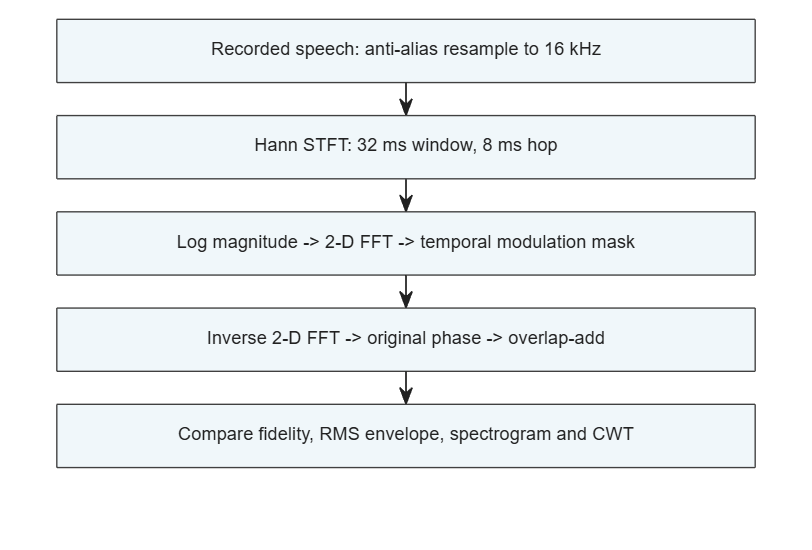

r2_plot([],1);

Figure 1. Processing pipeline. The CWT is an analysis branch after reconstruction, not a synthesis stage. All non-toolbox operations are included as separate r2_*.m helper files.

### 2.5 Code and Results

#### 2.5.1 Input preparation and reproducible analysis

[source, sourceFs] = audioread( ...
    fullfile(reportFolder,'voicebank_p232_003.wav'));
assert(sourceFs==48000 && size(source,2)==1);
fs = 16000;
x = resample(source,1,3);
x = x-mean(x);
x = 0.8*x/max(abs(x));
R = r2_analyse(x,fs);
fprintf('Duration: %.6f s; sample rate: %d Hz\n',numel(x)/fs,fs);

Duration: 7.184875 s; sample rate: 16000 Hz


fprintf('Score interval: %.3f to %.3f s\n',R.scoreRangeSeconds);

Score interval: 0.500 to 6.685 s


r2_stft and r2_istft contain the padded analysis/synthesis pair. r2_modfilter implements the reflected extension and temporal mask. r2_analyse applies the same settings to every condition and computes all metrics. No downloaded resources or external project paths are accessed during execution.

#### 2.5.2 Reconstruction and modulation calibration

for k=1:height(R.checks)
    fprintf('%s: %.3g (pass=%d)\n', ...
        R.checks.Check(k),R.checks.Value(k),R.checks.Passed(k));
end

Unit-gain STFT reconstruction: 2e-16 (pass=1)
Unmodified 2-D FFT round trip: 6.75e-16 (pass=1)
Constant log-spectrogram preservation: 1.78e-15 (pass=1)
4 Hz calibration amplitude error: 4.44e-15 (pass=1)
16 Hz calibration residual amplitude: 8.52e-15 (pass=1)
Maximum inverse-FFT imaginary error: 0 (pass=1)


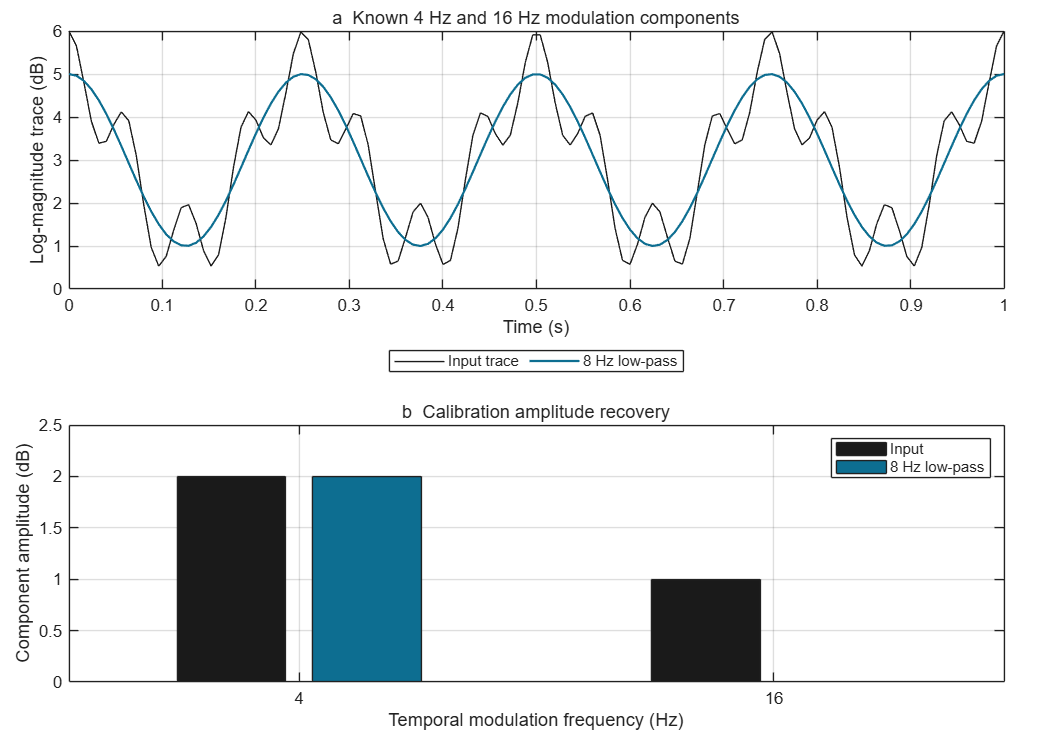

assert(all(R.checks.Passed));
r2_plot(R,2);

Figure 2. Algorithm-level calibration, not a speech intelligibility test. The input log-spectrogram trace contains 4 Hz and 16 Hz components with amplitudes 2 dB and 1 dB. An 8 Hz mask preserves the 4 Hz component and suppresses 16 Hz to numerical precision. Unit-gain speech reconstruction has relative error approximately 2e-16. The unmodified two-dimensional transform, constant-input, and real-valued inverse checks also pass.

#### 2.5.3 Modulation representation and parameter choices

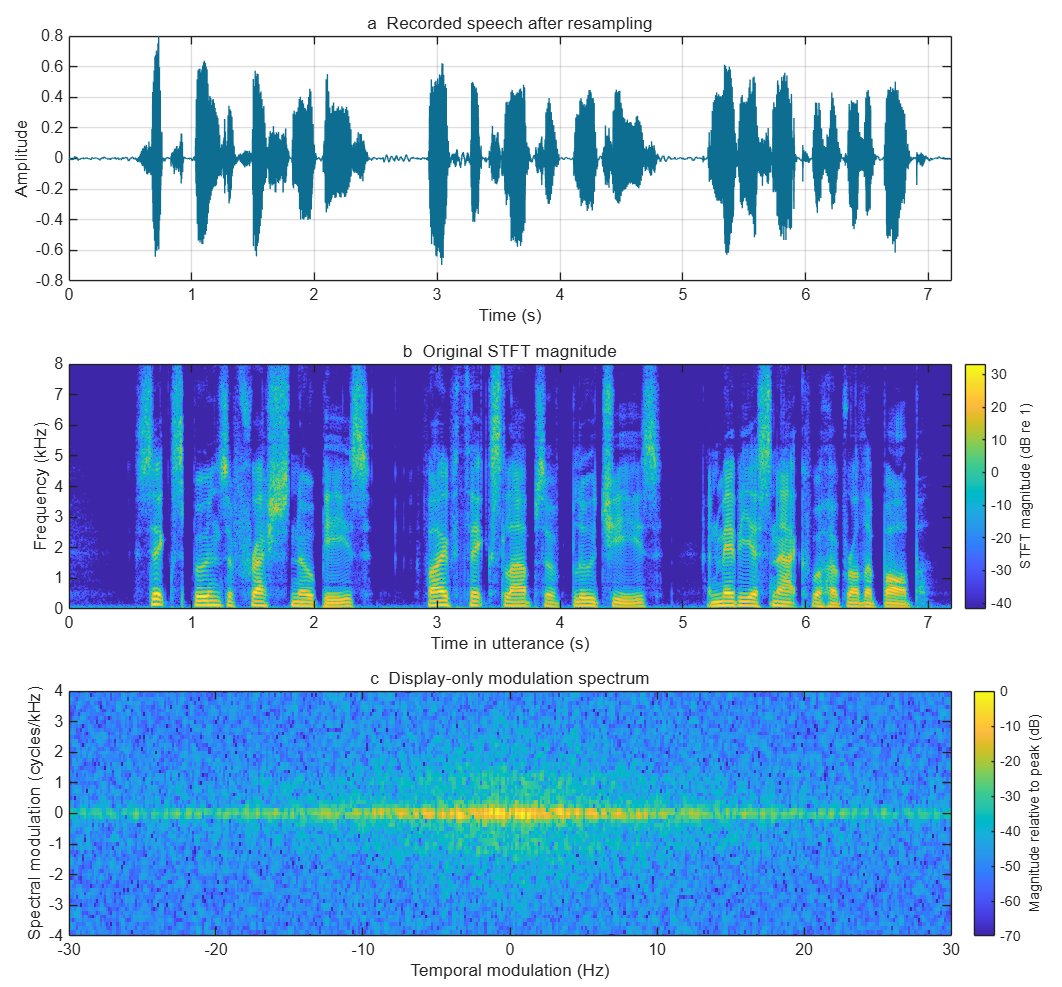

r2_plot(R,3);

Figure 3. Reference waveform, STFT magnitude, and display-only modulation spectrum. The modulation map uses a row-mean-removed, two-dimensional Hann-tapered log spectrogram and is normalised to its own peak. Its horizontal axis is temporal modulation in Hz; its vertical axis is spectral modulation in cycles/kHz.

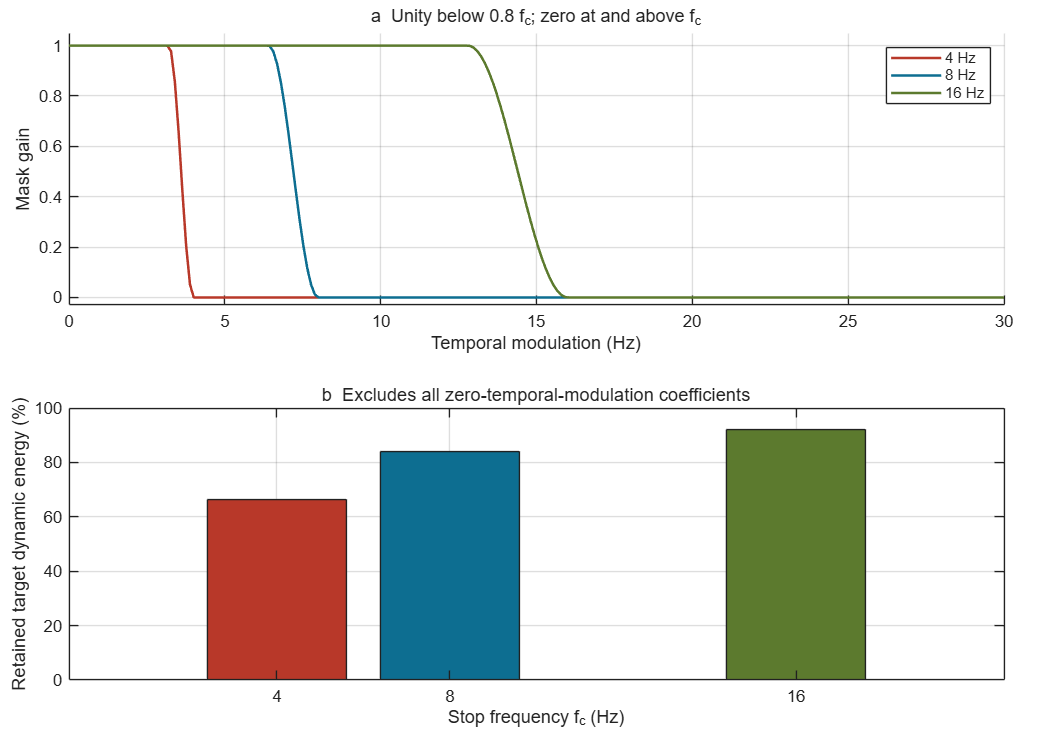

r2_plot(R,4);

Figure 4. Temporal mask responses and retained target dynamic-modulation energy. All coefficients with zero temporal modulation are excluded from this energy ratio, preventing static spectral structure from dominating the measure. The 4, 8, and 16 Hz masks retain 66.42%, 84.04%, and 92.28%, respectively. This is a target-spectrogram quantity, not a direct measurement of the reconstructed waveform's modulation energy.

The following executable block exposes the central operation for the 8 Hz condition. The helper applies the same operation to all settings. Reflection reduces the artificial boundary join but does not make the global FFT filter causal or eliminate all edge effects.

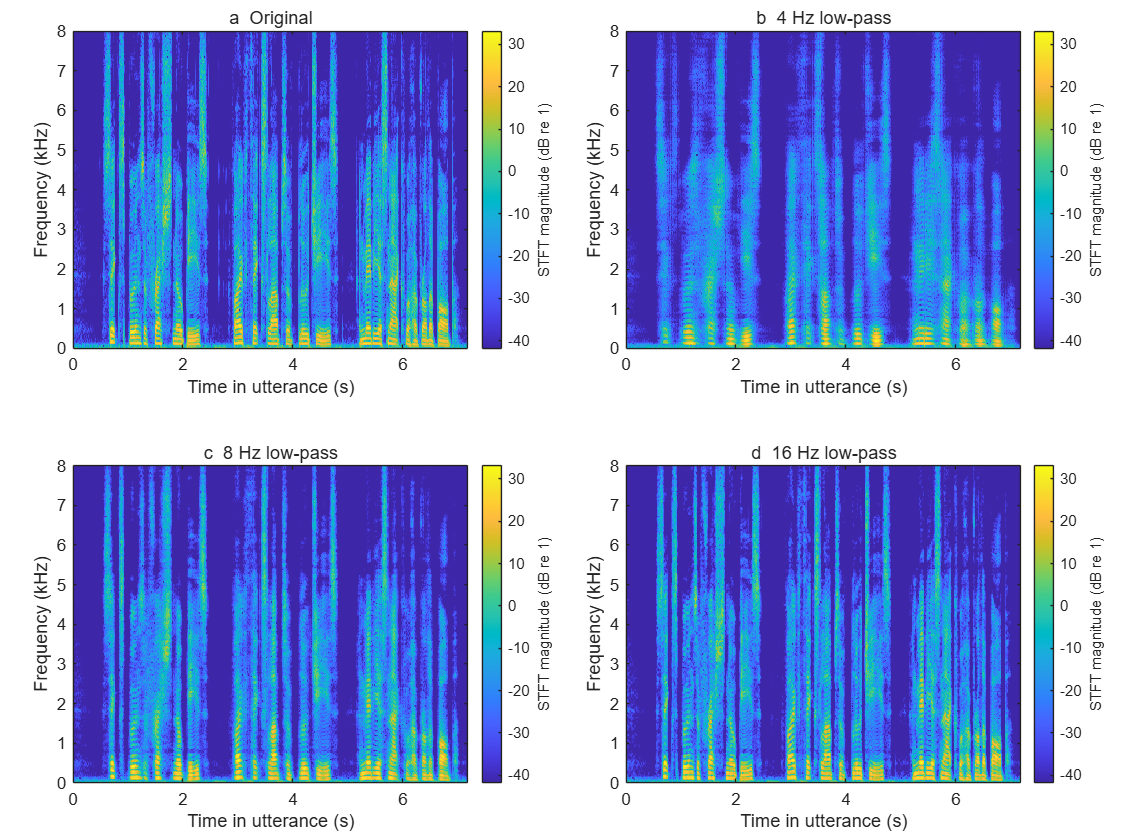

A = R.logMagnitude;
p = R.details{3}.paddingFrames;
A_pad = [A(:,p+1:-1:2), A, A(:,end-1:-1:end-p)];
M = fft2(A_pad);
B = ifftshift(R.details{3}.mask);
A_hat = real(ifft2(M.*B));
A_hat = A_hat(:,p+(1:size(A,2)));
S_hat = 10.^(A_hat/20).*exp(1i*angle(R.S));
S_hat([1 end],:) = real(S_hat([1 end],:));
x8 = r2_istft(S_hat,R.meta);
assert(max(abs(x8-R.outputs(:,3)))<1e-10);
r2_plot(R,5);

Figure 5. Reanalysed spectrograms of the original and three reconstructed waveforms. All panels use the same STFT grid and colour limits. These are actual reconstructed-output spectra, not the ideal filtered target matrices. Restricting modulation smooths temporal structure rather than imposing an acoustic low-pass cutoff at 4, 8, or 16 Hz.

#### 2.5.4 Quantitative fidelity and consistency

r2_print_metrics(R.metrics);

StopHz  Retained%  SNR_dB  EnvCorr  LogRMSE  Consistency
   Inf    100.00  313.98   1.0000     0.00    2.813e-16
     4     66.42    2.99   0.6206    10.99       0.2527
     8     84.04    5.70   0.8515     7.02       0.2088
    16     92.28   12.75   0.9763     4.21         0.16


Table 1. StopHz is the mask stop frequency (Inf denotes bypass); Retained% is target dynamic energy; EnvCorr is RMS-envelope correlation; LogRMSE is log-spectrum RMSE in dB; Consistency is relative complex-STFT error after reanalysis. Unlike the central-interval fidelity measures, consistency uses the complete padded STFT matrix. Bypass SNR is about 314 dB because only floating-point error remains, not a physical enhancement gain.

Increasing the cutoff from 4 to 16 Hz increased waveform SNR from 2.99 to 12.75 dB and reduced log-spectrum RMSE from 10.99 to 4.21 dB. The complete unrounded values are saved to generated/metrics.csv.

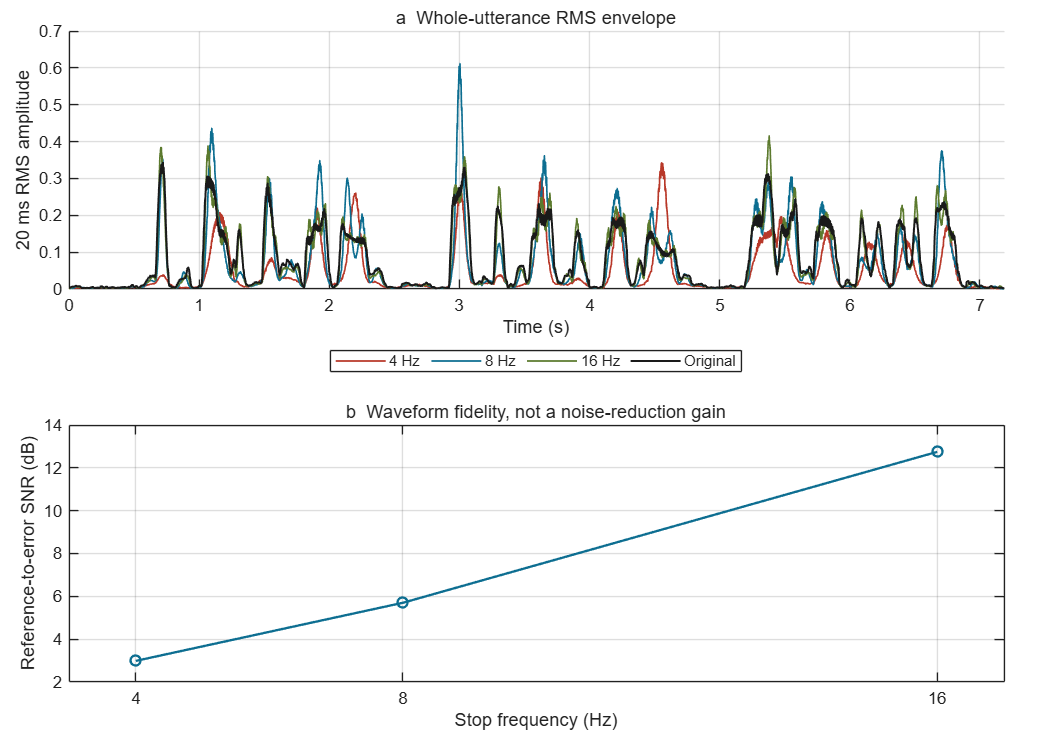

r2_plot(R,6);

Figure 6. Whole-utterance 20 ms RMS envelopes and scored waveform fidelity. The plotted envelopes include the boundaries for inspection, but all reported fidelity metrics exclude the first and last 0.5 s. The larger cutoff is closer to the original in this experiment; this does not establish better intelligibility.

#### 2.5.5 Local STFT and wavelet inspection

fprintf('Reference-selected event centre: %.4f s\n', ...
    (R.wavelet.eventSample-1)/fs);

Reference-selected event centre: 1.4931 s


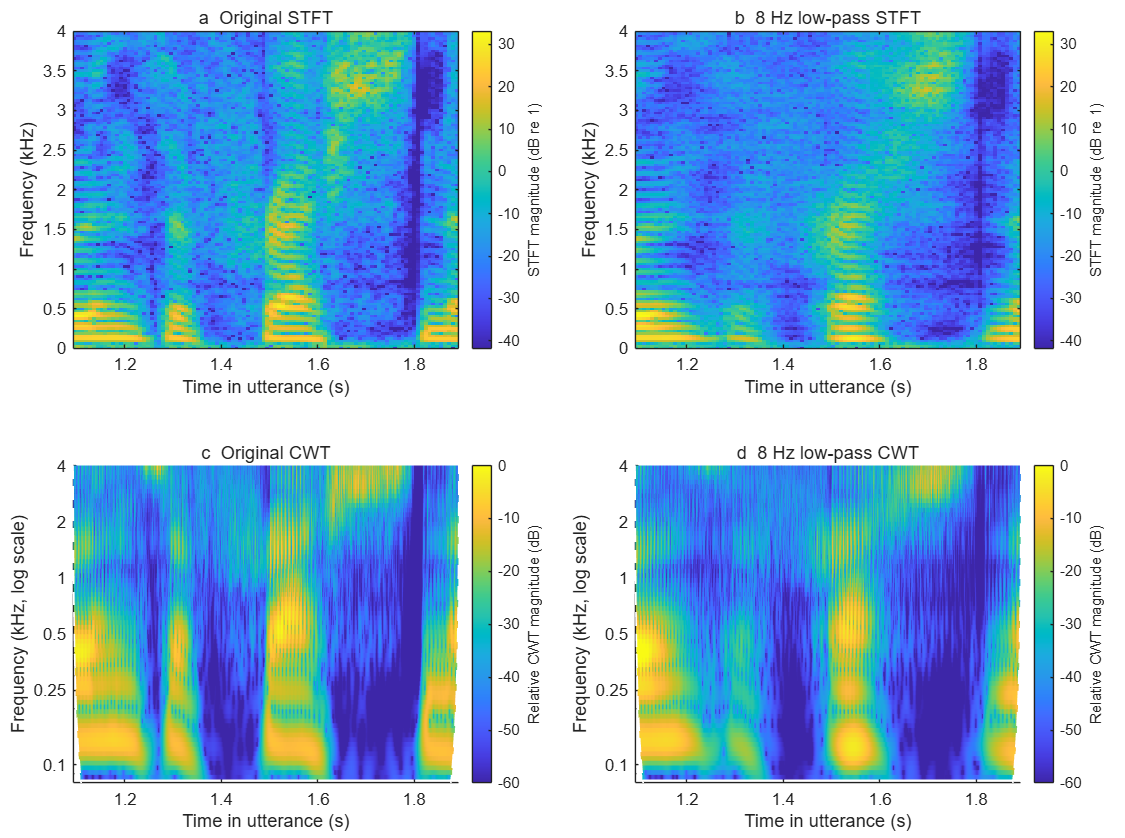

r2_plot(R,7);

r2_save(R,reportFolder);

Figure 7. One reference-selected 0.8 s event, comparing the original with the 8 Hz output. The upper row uses the same linear-frequency STFT scale. The lower row uses analytic Morlet CWT magnitudes on a logarithmic frequency axis, normalised to the original CWT peak with shared limits. COI-sensitive coefficients are omitted; dashed lines mark the COI where visible. STFT and CWT colours are not numerically interchangeable. The event is selected from the original envelope only, not from favourable output scores.

Optional listening: original.wav and modulation_lp4/8/16.wav are saved under generated/. They share one attenuation; none is independently peak-normalised. Listening is optional and is not part of the automated validation.

### 2.6 Discussion

Reducing the temporal cutoff removed rapid changes in the log spectrogram and reduced similarity to the original speech. The 16 Hz condition retained more dynamic-modulation energy and had higher envelope correlation than the 4 Hz condition. This direction agrees with the nested masks: increasing the cutoff preserves additional modulation coefficients. It does not demonstrate that 16 Hz is an optimal speech-processing setting, because the objective here was fidelity rather than a competing noise-removal benefit.

The distinction between modulation frequency and acoustic frequency is important. A 4 Hz temporal mask smooths changes in many acoustic-frequency channels; it does not restrict the audio waveform to frequencies below 4 Hz. The complementary CWT view retains a frequency-dependent temporal scale rather than the STFT's fixed window. Its boundary-sensitive regions were masked to avoid treating edge effects as speech events.

Reusing the original phase introduced a measurable limitation. The modified target spectrograms were not exactly consistent with their reconstructed waveforms: relative complex-STFT errors ranged from 0.160 to 0.253. Thus, the target energy-retention percentages cannot be read as exact waveform modulation retention. An iterative consistency reconstruction could be tested separately, but was not applied here.

The strongest checks are the near-exact bypass and known-component calibration, which distinguish deliberate modification from transform errors. Reflection and central-interval scoring reduce boundary sensitivity without removing the offline, global nature of filtering. Finally, only one utterance was examined. The speech-perception literature motivates the analysis [3], but neither the reported SNR nor envelope correlation establishes word recognition or listening quality. A controlled listening task would be needed for that conclusion.

### 2.7 Conclusion

This report implemented a reproducible MATLAB analysis of temporal modulation filtering in recorded speech. The pipeline connected STFT analysis, a two-dimensional modulation transform, controlled masks, overlap-add synthesis, and complementary CWT inspection. Reconstruction and known-component tests confirmed the transform and mask operations before the speech results were interpreted. Lower cutoffs retained less target dynamic energy and produced larger waveform and log-spectrum errors in the tested utterance. Original-phase reuse also produced nonzero STFT inconsistency, limiting how literally the ideal target can describe the output. The objective of demonstrating these representation and reconstruction trade-offs was met within this single-utterance offline experiment. No noise-reduction, real-time, or human-intelligibility improvement is claimed.

### 2.8 References

[1] University of Sydney. ELEC5305 Week5B: Modulation Spectra of Audio. Course MATLAB Live Script supplied for this unit; consulted October 2026.

[2] University of Sydney. ELEC5305 Week5Wavel: Time-Frequency Analysis with the Continuous Wavelet Transform. Course MATLAB Live Script; consulted October 2026.

[3] Elliott TM, Theunissen FE. The modulation transfer function for speech intelligibility. PLoS Computational Biology. 2009;5(3):e1000302. https://doi.org/10.1371/journal.pcbi.1000302

[4] MathWorks. fft2: 2-D fast Fourier transform. MATLAB Documentation. https://www.mathworks.com/help/matlab/ref/fft2.html (accessed 28 October 2026).

[5] MathWorks. cwt: Continuous 1-D wavelet transform. Wavelet Toolbox Documentation. https://www.mathworks.com/help/wavelet/ref/cwt.html (accessed 28 October 2026).

[6] MathWorks. Boundary Effects and the Cone of Influence. Wavelet Toolbox Documentation. https://www.mathworks.com/help/wavelet/ug/boundary-effects-and-the-cone-of-influence.html (accessed 28 October 2026).

[7] Valentini-Botinhao C. Noisy speech database for training speech enhancement algorithms and TTS models, 2016 [sound]. University of Edinburgh; 2017. https://doi.org/10.7488/ds/2117. Clean file: p232_003.wav; attribution and licence in AUDIO_SOURCE.txt.

[8] MathWorks. resample: Resample uniform or nonuniform data to new fixed rate. Signal Processing Toolbox Documentation. https://www.mathworks.com/help/signal/ref/resample.html (accessed 28 October 2026).